clear all
close all

## RQ1: Users statistics

%Load the csv file for RQ1 that was preprocessed in Python
data=readtable("yelp_Q1_business.csv")

data = 36500×7 table
           business_id                                                        categories                                                     city         review_count_business                        name                        state     stars_business
    __________________________    __________________________________________________________________________________________________    ______________    _____________________    ____________________________________________    ______    ______________

    {'LUvxyWag5gpiubSxOvR92A'}    {'['Mattresses', 'Shopping', 'Home Decor', 'Home & Garden', 'Furniture Stores']'                 }    {'Chandler'  }               3             {'Sleep Number'                            }    {'AZ'}   

data1=readtable("yelp_Q1_users.csv")

data1 = 247028×24 table
                    votes_x                              user_id                      review_id             stars       date                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                               

%%%Save user and business reviews data%%%%

%Business reviews 
reviews_user=data(:,"review_count_business");
r=table2array(reviews_user)

r =      3
     3
    20
     6
     8
     3
     3
    28
    18
     3



%User reviews 
reviews_user1=data1(:,"review_count");
r1=table2array(reviews_user1)

r1 =      7
     2
    35
    21
    19
    14
    24
    38
    50
    70


%%%BUSINESS REVIEWS

%Estimate the first four moments of the business reviews distribution
N=numel(r); %length of reviews vector 
m = sum(r)/N; % Compute mean and store value in variable
s = sqrt(sum((r-m).^2)/N); % Compute std. deviation and store value in variable
fprintf('\n')
fprintf('Mean = %4.3f\n',m)

Mean = 30.433


fprintf('Std. deviation = %4.3f\n',s)

Std. deviation = 70.121



fprintf('Skewness = %4.3f\n',sum((r-m).^3)/(N*s^3))

Skewness = 8.147



fprintf('Excess kurtosis = %4.3f\n',sum((r-m).^4)/(N*s^4)-3)

Excess kurtosis = 112.197



fprintf('\n')

%Skewness and Excess kurtosis tells us whetehr our data is close to
%Gaussian (skewness=0 & kurtosis =3). A markedly positive value indicates
%large excess kurotiss with respect to Gaussian. Empirical dist of returns
%is leptokurtic (significant kurtosis) --> our data has heavy tails. 
%Skewness measures symmetry. Gaussian is perfectly symmetric. Our dist has
%positive skewness.

%%USER REVIEWS%%%

%Estimate the first four moments of the user reviews distribution
N1=numel(r1); %length of reviews vector 
m1 = sum(r1)/N1; % Compute mean and store value in variable
s1 = sqrt(sum((r1-m1).^2)/N1); % Compute std. deviation and store value in variable
fprintf('\n')
fprintf('Mean = %4.3f\n',m1)

Mean = 21.236


fprintf('Std. deviation = %4.3f\n',s1)

Std. deviation = 86.877



fprintf('Skewness = %4.3f\n',sum((r1-m1).^3)/(N1*s1^3))

Skewness = 19.633



fprintf('Excess kurtosis = %4.3f\n',sum((r1-m1).^4)/(N1*s1^4)-3)

Excess kurtosis = 993.435



fprintf('\n')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% Sample values from Gaussian pdf  %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%(business reviews)

n=100; %number of points in the grid
stepsize=round(((m+5*s)-min(r(r>0)))/n)

stepsize = 4

x = round(min(r(r>0))):stepsize:round(m+5*s) % Point grid between min and max return

x =      3     7    11    15    19    23    27    31    35    39    43    47    51    55    59    63    67    71    75    79    83    87    91    95    99   103   107   111   115   119   123   127   131   135   139   143   147   151   155   159   163   167   171   175   179   183   187   191   195   199


g = exp(-(x-m).^2/(2*s^2))/sqrt(2*pi*s^2) % Gaussian PDF values computed on point grid

g =     0.0053    0.0054    0.0055    0.0056    0.0056    0.0057    0.0057    0.0057    0.0057    0.0056    0.0056    0.0055    0.0054    0.0054    0.0052    0.0051    0.0050    0.0048    0.0046    0.0045    0.0043    0.0041    0.0039    0.0037    0.0035    0.0033    0.0031    0.0029    0.0027    0.0026    0.0024    0.0022    0.0020    0.0019    0.0017    0.0016    0.0014    0.0013    0.0012    0.0011    0.0010    0.0009    0.0008    0.0007    0.0006    0.0005    0.0005    0.0004    0.0004    0.0003



%(user reviews)

n=100; %number of points in the grid
%stepsize=round((max(r)-min(r))/n);
stepsize=round(((m1+5*s1)-min(r1(r1>0)))/n)
x1 = round(min(r1(r1>0))):stepsize:round(m1+5*s1) % Point grid between min and max return
g1 = exp(-(x1-m1).^2/(2*s1^2))/sqrt(2*pi*s1^2) % Gaussian PDF values computed on point grid

stepsize = 5

x1 =      1     6    11    16    21    26    31    36    41    46    51    56    61    66    71    76    81    86    91    96   101   106   111   116   121   126   131   136   141   146   151   156   161   166   171   176   181   186   191   196   201   206   211   216   221   226   231   236   241   246


g1 =     0.0045    0.0045    0.0046    0.0046    0.0046    0.0046    0.0046    0.0045    0.0045    0.0044    0.0043    0.0042    0.0041    0.0040    0.0039    0.0038    0.0036    0.0035    0.0033    0.0032    0.0030    0.0029    0.0027    0.0025    0.0024    0.0022    0.0021    0.0019    0.0018    0.0016    0.0015    0.0014    0.0013    0.0011    0.0010    0.0009    0.0008    0.0008    0.0007    0.0006    0.0005    0.0005    0.0004    0.0004    0.0003    0.0003    0.0002    0.0002    0.0002    0.0002


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% Compare the empirical dist. of the data with Gaussian pdf %%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Considering the values of skewness and Kurtosis we expect that the distribution is
%not Gaussian. In fact we expect large positive deviations from the mean and the presence of fat-tails. 
%Max likelihood tells that the most appropriate Gaussian dist to describe
%the data is the one with same mean and std as the sample mean and std. 

close all
subplot(3,2,1)

%plotting histogram of dataset to compare it with Gaussian

NB = 30; % Number of bins for histogram of returns
h=histogram(r,NB,'Normalization','PDF')

h =   Histogram with properties:

             Data: [36500×1 double]
           Values: [1×30 double]
          NumBins: 30
         BinEdges: [0 65 130 195 260 325 390 455 520 585 650 715 780 845 910 975 1040 1105 1170 1235 1300 1365 1430 1495 1560 1625 1690 1755 1820 1885 1950]
         BinWidth: 65
        BinLimits: [0 1950]
    Normalization: 'pdf'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


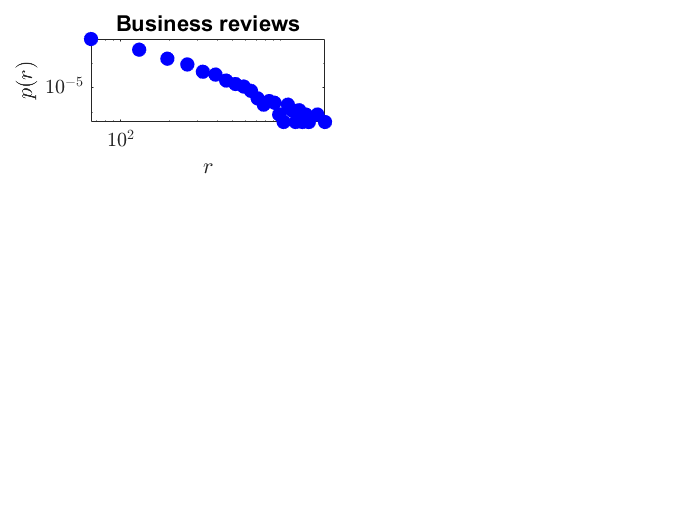

plot(h.BinEdges(1:NB),h.Values,'ob','MarkerSize',8,'MarkerFaceColor','b')

hold on
%plot(x,g,'r','LineWidth',2)
set(gca,'YScale','log')  %log scale in y-axis to identify better the differences. Gaussian decaying exponentially- presence of fat tail is obvious
%log scale to identify better the deviations in the tail 
set(gca,'XScale','log')  %log scale in y-axis to identify better the differences. Gaussian decaying exponentially- presence of fat tail is obvious


xlabel('$r$','Interpreter','LaTex')
ylabel('$p(r)$','Interpreter','LaTex')
set(gca,'TickLabelInterpreter','LaTex')
set(gca,'FontSize',12)
title('Business reviews')


%We observe large deviation from Gaussian in the right tail. Gaussian
%decays much faster(exponentially) while our distribution decays much
%slowly. (i.e. more extreme events than predicted by a Gaussian). THe exess
%of mass in the tail is compensated by a lack of mass in the centre.
%Visually validate clear differences between the empirical distribution and
%the Gaussian distribution

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% Plot of empirical CCDF vs Gaussian %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%CCDF plot shows that the Gaussian distribution indicates higher probab of
%%empirical pdfs for values greater than > r*
%%probability
x = sort(r); % Returns sorted in ascending order
y = 1:1:length(r);
y = 1 - y/(length(r)+1); % Calculating CCDF as rank-frequency plot
c = 0.5*(1 - erf((x-m)./(s*sqrt(2)))); % Gaussian CCDF
 
subplot(3,2,2)
semilogy(x,y,'b','LineWidth',2) %empirical CCDF of data
hold on
semilogy(x,c,'r','LineWidth',2)
set(gca,"Xscale","log")
ylim([1e-4 1])
xlim([min((r(r>0))) max(r)])
xlabel('$r$','Interpreter','LaTex')
ylabel('$C(r)$','Interpreter','LaTex')
set(gca,'TickLabelInterpreter','LaTex')
set(gca,'FontSize',12)
title('CCDF business reviews')
legend("Data","Gaussian")

subplot(3,2,3)

%plotting histogram of dataset to compare it with Gaussian

%plotting histogram of dataset to compare it with Gaussian

NB1 = 30; % Number of bins for histogram of returns
h1=histogram(r1,NB1,'Normalization','PDF')

h1 =   Histogram with properties:

             Data: [247028×1 double]
           Values: [0.0031 2.4074e-05 5.8445e-06 2.3403e-06 1.0879e-06 4.6806e-07 2.6566e-07 7.5902e-08 1.3915e-07 7.5902e-08 5.0602e-08 2.5301e-08 2.5301e-08 0 0 0 0 0 0 0 1.2650e-08 0 0 0 0 0 0 0 0 1.2650e-08]
          NumBins: 30
         BinEdges: [0 320 640 960 1280 1600 1920 2240 2560 2880 3200 3520 3840 4160 4480 4800 5120 5440 5760 6080 6400 6720 7040 7360 7680 8000 8320 8640 8960 9280 9600]
         BinWidth: 320
        BinLimits: [0 9600]
    Normalization: 'pdf'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


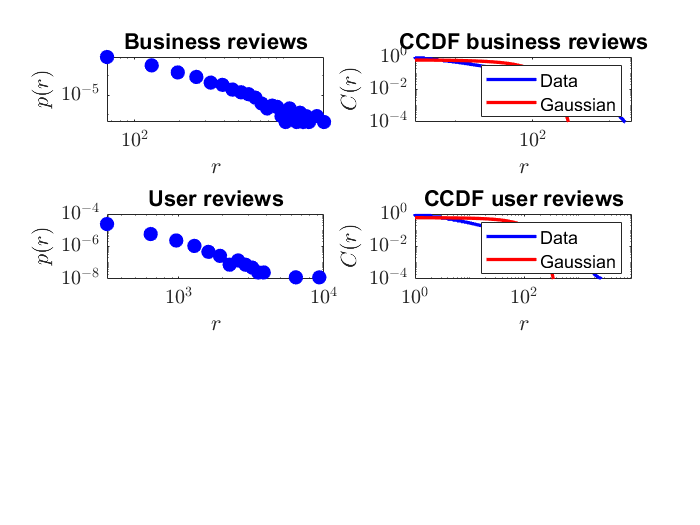

h1 =   Histogram with properties:

             Data: [247028×1 double]
           Values: [0.0031 2.4074e-05 5.8445e-06 2.3403e-06 1.0879e-06 4.6806e-07 2.6566e-07 7.5902e-08 1.3915e-07 7.5902e-08 5.0602e-08 2.5301e-08 2.5301e-08 0 0 0 0 0 0 0 1.2650e-08 0 0 0 0 0 0 0 0 1.2650e-08]
          NumBins: 30
         BinEdges: [0 320 640 960 1280 1600 1920 2240 2560 2880 3200 3520 3840 4160 4480 4800 5120 5440 5760 6080 6400 6720 7040 7360 7680 8000 8320 8640 8960 9280 9600]
         BinWidth: 320
        BinLimits: [0 9600]
    Normalization: 'pdf'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


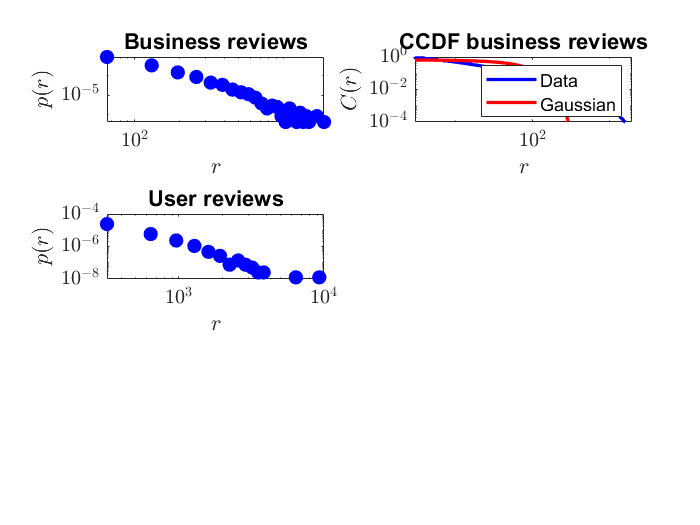

plot(h1.BinEdges(1:NB),h1.Values,'ob','MarkerSize',8,'MarkerFaceColor','b')

hold on
%plot(x1,g1,'r','LineWidth',2)
set(gca,'YScale','log')  %log scale in y-axis to identify better the differences. Gaussian decaying exponentially- presence of fat tail is obvious
%log scale to identify better the deviations in the tail 
set(gca,'XScale','log')  %log scale in y-axis to identify better the differences. Gaussian decaying exponentially- presence of fat tail is obvious

%ylim([10^-6 10^-2])
%xlim([min(r(r>0)) 1000])

%xlim([10^2 max(r)])
xlabel('$r$','Interpreter','LaTex')
ylabel('$p(r)$','Interpreter','LaTex')
set(gca,'TickLabelInterpreter','LaTex')
set(gca,'FontSize',12)
title('User reviews')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% Plot of empirical CCDF vs Gaussian %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%CCDF plot shows that the Gaussian distribution indicates higher probab of
%%empirical pdfs for values greater than > r*
%%probability
x1 = sort(r1); % Returns sorted in ascending order
y1 = 1:1:length(r1);
y1 = 1 - y1/(length(r1)+1); % Calculating CCDF as rank-frequency plot
c1 = 0.5*(1 - erf((x1-m1)./(s1*sqrt(2)))); % Gaussian CCDF
 

subplot(3,2,4)
semilogy(x1,y1,'b','LineWidth',2) %empirical CCDF of data
hold on
semilogy(x1,c1,'r','LineWidth',2)
set(gca,"Xscale","log")
ylim([1e-4 1])
xlim([min((r1(r1>0))) max(r1)])
xlabel('$r$','Interpreter','LaTex')
ylabel('$C(r)$','Interpreter','LaTex')
set(gca,'TickLabelInterpreter','LaTex')
set(gca,'FontSize',12)
title('CCDF user reviews')
legend("Data","Gaussian")

%%%Reload the review data)
reviews_user=data(:,"review_count_business");
r=table2array(reviews_user)

r =      3
     3
    20
     6
     8
     3
     3
    28
    18
     3


reviews_user1=data1(:,"review_count");
r1=table2array(reviews_user1)

r1 =      7
     2
    35
    21
    19
    14
    24
    38
    50
    70


r1 =      7
     2
    35
    21
    19
    14
    24
    38
    50
    70



ans =

  0×1 empty double column vector



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% Various distribution fittings %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Business reviews
Lognorm=fitdist(r,"Lognormal");
Exponential=fitdist(r,"Exponential");
Pareto=fitdist(r,"GeneralizedPareto");
Gamma=fitdist(r,"Gamma");
Kernel=fitdist(r,"Kernel");
%Beta=fitdist(r,"Stable");

%User reviews
Lognorm1=fitdist(r1(r1>0),"Lognormal");
Exponential1=fitdist(r1,"Exponential");
Pareto1=fitdist(r1(r1>0),"GeneralizedPareto");
Gamma1=fitdist(r1(r1>0),"Gamma");
Kernel1=fitdist(r1(r1>0),"Kernel");
%Beta=fitdist(r,"Stable");


%%%%%%%% Sample values for the different distributions fitted above%%%%%%%%%%%%

%Business reviews
x=min(r(r>0)):20:max(r);
pdfLognorm=pdf(Lognorm,x);
pdfExponential=pdf(Exponential,x);
pdfPareto=pdf(Pareto,x);
pdfKernel=pdf(Kernel,x);

%User reviews
x1=min(r1(r1>0)):20:max(r1);
pdfLognorm1=pdf(Lognorm1,x1);
pdfExponential1=pdf(Exponential1,x1);
pdfPareto1=pdf(Pareto1,x1);
pdfKernel1=pdf(Kernel1,x1);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% Plot distributions fittings %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

subplot(3,2,5)
NB=30

NB = 30

histogram(r,NB,'Normalization','PDF')
%plot(h.BinEdges(1:NB),h.Values,'ob','MarkerSize',8,'MarkerFaceColor','b')

hold on
% line(x,pdfLognorm,'Color','r',"LineWidth",2)
% line(x,pdfExponential,"Color",'b',"LineWidth",2)
line(x,pdfPareto,'Color','r',"LineWidth",2)
line(x,pdfKernel,'Color','k',"LineWidth",1)

legend('Data','Power Law',"Gaussian Kernel")
%title('MPG for Cars from USA')
%xlabel('MPG')
set(gca,"YScale","log")
%set(gca,"XScale","log")

ylim([10^-7 10^0])
xlim([0 1800])
set(gca,'FontSize',12)
title('Business reviews')

subplot(3,2,6)

NB=60

NB = 60

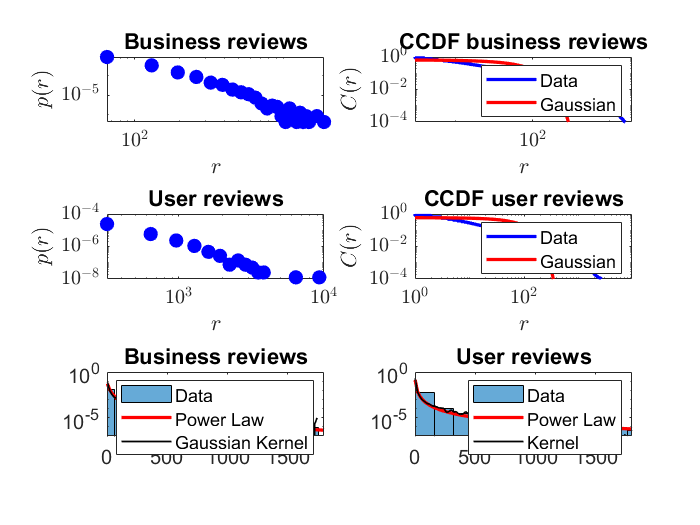

NB = 60

ans = 13.6998

histogram(r1,NB,'Normalization','PDF')
hold on
%line(x1,pdfLognorm,'Color','r',"LineWidth",2)
%line(x1,pdfExponential1,"Color",'b',"LineWidth",2)
line(x1,pdfPareto1,'Color','r',"LineWidth",2)
line(x1,pdfKernel1,'Color','k',"LineWidth",1)

legend('Data','Power Law',"Kernel")
%title('MPG for Cars from USA')
%xlabel('MPG')
set(gca,"YScale","log")
%set(gca,"XScale","log")

ylim([10^-7 10^0])
xlim([0 1800])
set(gca,'FontSize',12)
title('User reviews')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% QQ-Plot of Pareto dist vs. empirical dist %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%plots the quantile of the dist against each other. 

%Here we introduce a two-variable function defined as the difference
%between the Cumulative function of the pareto and a number. We will use it
%to solve numerically the inversion problem, since there is no close
%solution for C^-1 in the case of a Gaussian. So, instead of solving
%directly C^-1(u)=y, we will numerically serach for a zero of the equation
%C(y)-u=0. 

%Generation of random numbers from a target dist. We'll keep our empirical
%data ([train_set val_set]), then will generate r.n dist acc. to Gaussian
%Kernel. This will be done with the inversion of CDF. Take a unifrom random
%number, apply the inverse of CDF to get the output y which is a r.n dist.
%accotding to the target dist of choice.
%To do that first define Gaussian Kernel CDF. Then substrat u. We want to
%evaluate C(y)-u=0, using the fzero. 

close all

figure(3)
k=Pareto.k;
sigma=Pareto.sigma;
theta=Pareto.theta;

n_rand = 5000; % Number of random numbers to be generated
pareto_random_numbers=[]


pareto_random_numbers =

     []



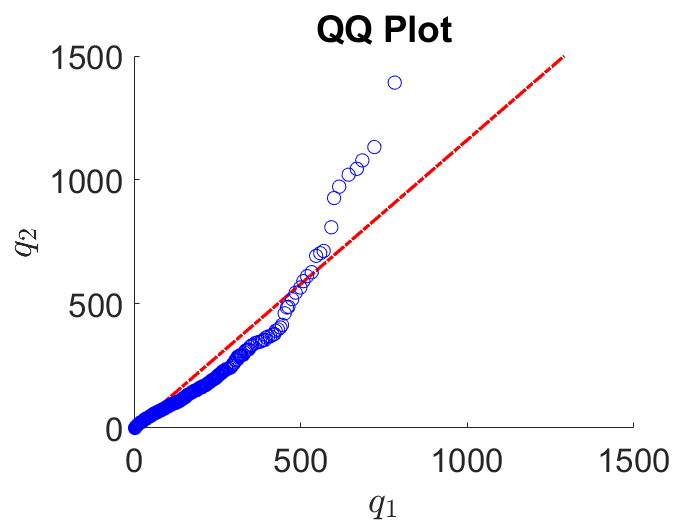


for i = 1:n_rand
   
    u = rand; % Random number drawn from uniform distribution over [0,1] 
    
    y=gprnd(k,sigma,theta);
    
    pareto_random_numbers = [pareto_random_numbers; y];
    
end

%qqplot(x,y) displays a quantile-quantile plot of the quantiles of the sample data x versus the quantiles of the sample data y. If the samples come from the same distribution, then the plot appears linear.
%plot of the quantile of a target dist (line in red) vs. quantiles of an
%empirical dist. This allows us to conclude that we're doing a faily good
%job because the central body of the dist falls into the line.
%pvec = 0:1:100; % Vector of quantiles to be plotted
h = qqplot(r,pareto_random_numbers);%,pvec); %Double check
set(h(1),'marker','o','markersize',8,'markeredgecolor','blue');
set(h(2),'linewidth',2,'color','red');
set(h(3),'linewidth',2,'color','red');

set(gca,'FontSize',20)
title('QQ Plot')
ylim([0 1500])
xlabel('$q_1$','Interpreter','LaTex')
ylabel('$q_2$','Interpreter','LaTex')


pval=0.05;

[b,p] = kstest2(r,pareto_random_numbers,pval);
if b == 1
   fprintf('NH rejected at %3.2f significance level (p = %3.2e)\n',pval,p)
elseif b == 0
   fprintf('NH cannot be rejected at %3.2f significance level (p = %3.2e)\n',pval,p)
end

NH rejected at 0.05 significance level (p = 3.36e-134)



fprintf('\n')

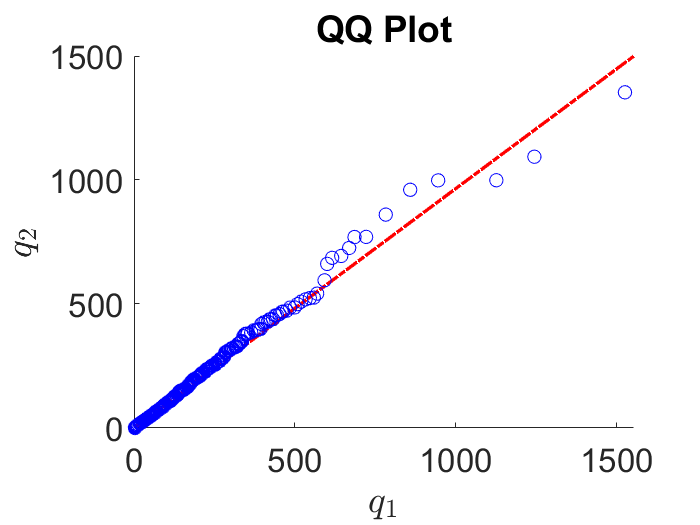

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% QQ-Plot of Kernel dist vs. empirical dist %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%plots the quantile of the dist against each other. 

%Here we introduce a two-variable function defined as the difference
%between the Cumulative function of the pareto and a number. We will use it
%to solve numerically the inversion problem, since there is no close
%solution for C^-1 in the case of a Gaussian. So, instead of solving
%directly C^-1(u)=y, we will numberically serach for a zero of the equation
%C(y)-u=0. 

%Generation of random numbers from a target dist. We'll keep our empirical
%data ([train_set val_set]), then will generate r.n dist acc. to Gaussian
%Kernel. This will be done with the inversion of CDF. Take a unifrom random
%number, apply the inverse of CDF to get the output y which is a r.n dist.
%accotding to the target dist of choice.
%To do that first define Gaussian Kernel CDF. Then substrat u. We want to
%evaluate C(y)-u=0, using the fzero. 

close all

r=table2array(reviews_user);

figure(4)
b=Kernel.BandWidth;

pt=0.33; %fraction of data to use in trainign set
pv=0.33; %fraction of data to use in validation set
train_set=r(1:round(pt*length(r)));
N_T=length(train_set);
val_set=r(round(pt*length(r)+1:round((pt+pv)*length(r))));
test_set=r(round((pt+pv)*length(r))+1:end);

f = @(x,u) sum(1+erf((x-train_set)/sqrt(2*b^2)))/(2*N_T) - u;

n_rand = 5000; % Number of random numbers to be generated

kernel_random_numbers = []; % Vector to store all random numbers to be generated

for i = 1:n_rand
   
    u = rand; % Random number drawn from uniform distribution over [0,1] 
    
    y = fzero(@(x) f(x,u),0); % Numerical solution of the equation C(y)-u = 0
    
    kernel_random_numbers = [kernel_random_numbers; y];
    
end

%qqplot(x,y) displays a quantile-quantile plot of the quantiles of the sample data x versus the quantiles of the sample data y. If the samples come from the same distribution, then the plot appears linear.
%plot of the quantile of a target dist (line in red) vs. quantiles of an
%empirical dist. This allows us to conclude that we're doing a faily good
%job because the central body of the dist falls into the line.
%pvec = 0:1:100; % Vector of quantiles to be plotted
h = qqplot(r,kernel_random_numbers);%,pvec); %Double check
set(h(1),'marker','o','markersize',8,'markeredgecolor','blue');
set(h(2),'linewidth',2,'color','red');
set(h(3),'linewidth',2,'color','red');

set(gca,'FontSize',20)
title('QQ Plot')
xlabel('$q_1$','Interpreter','LaTex')
ylabel('$q_2$','Interpreter','LaTex')
ylim([0 1500])

pval=0.05;

[b,p] = kstest2(r,kernel_random_numbers,pval);
if b == 1
   fprintf('NH rejected at %3.2f significance level (p = %3.2e)\n',pval,p)
elseif b == 0
   fprintf('NH cannot be rejected at %3.2f significance level (p = %3.2e)\n',pval,p)
end

NH rejected at 0.05 significance level (p = 7.62e-30)



fprintf('\n')

%%%%%%%%RIGHT TAIL FITTING AND Kolmogorov-Smirnov TEST (Business reviews) %%%%%%
close all

r=table2array(reviews_user)

r =      3
     3
    20
     6
     8
     3
     3
    28
    18
     3



r = sort(r); % Sorting returns

% p=r(find(r<=xmin))/length(r)
% p=1-p(end)

perc=logspace(-1,-1.5,1000); 
pval=0.05

pval = 0.0500



Alphas=[];
PValues=[];
%%% Right tail %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for i=1:length(perc)
    r_right = r(round((1-perc(i))*length(r)):end); % Selecting top p% of returns
    N = length(r_right);
    alpha_right = N/sum(log(r_right/min(r_right))); % Maximum-likelihood estimate for right tail exponent
    n=10000;
    %x=xmin:1:r_right(end)
    alpha=alpha_right;
    xmin=min(r_right);
    u=rand(n,1);
    power_law_random=xmin*u.^(-1/alpha);
    [b,p] = kstest2(r_right,power_law_random,pval);
    Alphas=[Alphas; alpha_right];
    PValues=[PValues; p];
end


perc=perc(find(PValues==max(PValues)))

perc = 0.0409

alpha_right=Alphas(find(PValues==max(PValues)))

alpha_right = 1.8136

r_right = r(round((1-perc)*length(r)):end)

r_right =    145
   146
   146
   146
   146
   146
   146
   146
   146
   147


xmin=min(r_right);
fprintf('Right tail exponent: %4.3f\n',alpha_right)

Right tail exponent: 1.814


fprintf('Xmin: %4.3f\n',xmin)

Xmin: 145.000


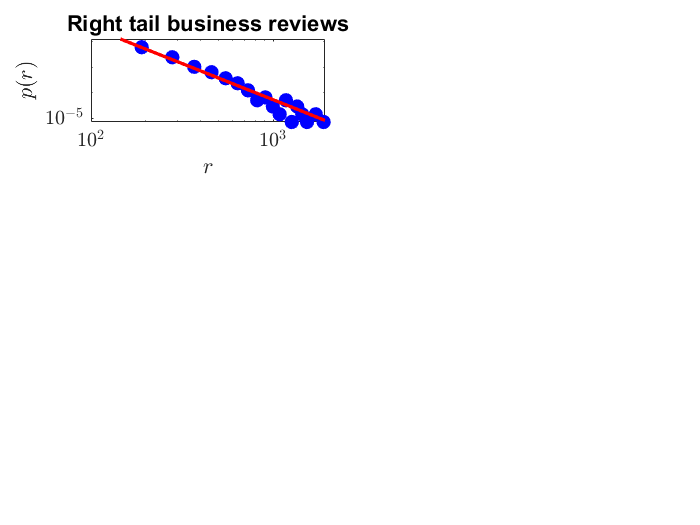


n=100; %number of points in the grid
stepsize=round((max(r_right)-min(r_right))/n);
stepsize;
x_right = min(r_right):stepsize:max(r_right); % Point grid between min and max return
y_right = alpha_right*(x_right/min(r_right)).^(-alpha_right-1)/min(r_right); % Values of power law distribution on grid of points

%Visual comparison between our data and the power law dist which in loglog
% scale is a linear function. histnorm command produces a normalised
% histogram of the dataset. Input is our r_right vector and asking this func
% to produce a histogram with 20 bins. This command produces in output two
% vectors (y,x) coordinates of the bins of this histogram. a_righ centers of
% the bins; b_right is the height of the bins. 

[b_right,a_right] = histnorm(r_right,20); %a_right centres of the bins' b_right height of the bins

subplot(3,2,1)
loglog(a_right,b_right,'ob','MarkerSize',8,'MarkerFaceColor','b')
hold on
loglog(x_right,y_right,'r','LineWidth',2)

xlabel('$r$','Interpreter','LaTex')
ylabel('$p(r)$','Interpreter','LaTex')

set(gca,'TickLabelInterpreter','LaTex')
set(gca,'FontSize',12)
title('Right tail business reviews')

%MAx likelihood tells us that right tail exponent is: . and a visual
%comparison between the data and distribution we have fitted indicates a
%reasonable fit (at least visually).
%As of now we haven't seen the tools of making a reasonable comparison
%between empirical dist and the theoretical dist. Upcoming lectures.
%VIsually given that our data follow a negative slope it indicates that at
%least in the tail we have a power law beahviour. 

%%%%%%%%RIGHT TAIL FITTING AND KS TEST (user reviews) %%%%%%

r1=table2array(reviews_user1)

r1 =      7
     2
    35
    21
    19
    14
    24
    38
    50
    70



r1 = sort(r1); % Sorting returns

% p=r(find(r<=xmin))/length(r)
% p=1-p(end)

perc1=logspace(-0.6,-2,1000); 
pval1=0.05

pval1 = 0.0500



Alphas1=[];
PValues1=[];
%%% Right tail %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for i=1:length(perc1)
    r_right1 = r1(round((1-perc1(i))*length(r1)):end); % Selecting top p% of returns
    N1 = length(r_right1);
    alpha_right1 = N1/sum(log(r_right1/min(r_right1))); % Maximum-likelihood estimate for right tail exponent
    n=10000;
    %x=xmin:1:r_right(end)
    alpha1=alpha_right1;
    xmin1=min(r_right1);
    u=rand(n,1);
    power_law_random1=xmin1*u.^(-1/alpha1);
    [b1,p1] = kstest2(r_right1,power_law_random1,pval1);
    Alphas1=[Alphas1; alpha_right1];
    PValues1=[PValues1; p1];
end


perc1=perc1(find(PValues1==max(PValues1)))

perc1 = 0.0109

alpha_right1=Alphas1(find(PValues1==max(PValues1)))

alpha_right1 = 1.8180

r_right1 = r1(round((1-perc1)*length(r1)):end)

r_right1 =    322
   322
   322
   322
   322
   322
   322
   322
   322
   322


xmin1=min(r_right1);
fprintf('Right tail exponent: %4.3f\n',alpha_right1)

Right tail exponent: 1.818


fprintf('Xmin: %4.3f\n',xmin1)

Xmin: 322.000


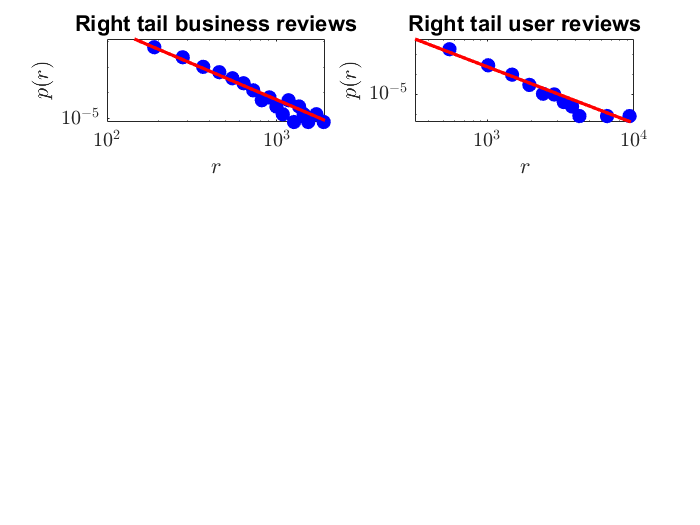


n=100; %number of points in the grid
stepsize=round((max(r_right1)-min(r_right1))/n);
stepsize;
x_right1 = min(r_right1):stepsize:max(r_right1); % Point grid between min and max return
y_right1 = alpha_right1*(x_right1/min(r_right1)).^(-alpha_right1-1)/min(r_right1); % Values of power law distribution on grid of points

%Visual comparison between our data and the power law dist which in loglog
% scale is a linear function. histnorm command produces a normalised
% histogram of the dataset. Input is our r_right vector and asking this func
% to produce a histogram with 20 bins. This command produces in output two
% vectors (y,x) coordinates of the bins of this histogram. a_righ centers of
% the bins; b_right is the height of the bins. 

[b_right1,a_right1] = histnorm(r_right1,20); %a_right centres of the bins' b_right height of the bins

subplot(3,2,2)
loglog(a_right1,b_right1,'ob','MarkerSize',8,'MarkerFaceColor','b')
hold on
loglog(x_right1,y_right1,'r','LineWidth',2)

xlabel('$r$','Interpreter','LaTex')
ylabel('$p(r)$','Interpreter','LaTex')

set(gca,'TickLabelInterpreter','LaTex')
set(gca,'FontSize',12)
title('Right tail user reviews')

%MAx likelihood tells us that right tail exponent is: . and a visual
%comparison between the data and distribution we have fitted indicates a
%reasonable fit (at least visually).
%As of now we haven't seen the tools of making a reasonable comparison
%between empirical dist and the theoretical dist. Upcoming lectures.
%VIsually given that our data follow a negative slope it indicates that at
%least in the tail we have a power law beahviour. 

%Reload Reviews data 
r=table2array(reviews_user);

r1=table2array(reviews_user1);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% Estimating bandwidth of Kernel param for x<xmin based on MLE %%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%Business reviews%%%

%Kernel densities tailored on a specific dataset and almost assumptions
%free. In Kernel density the only assumption you need to make is the Kernel
%function. We'll use a standard Gaussian pdf for our k. 

%Use Gaussian mix plot to plot a Gaussian Kernel function. Gaussian needs a
%vector of means and a std parameter.

%Separating the data into training/validation and testing set(one third of
%the data each). You need a portion of the data (train) as your vector of
%points that will define the means of local kernels (Gaussians). A portion
%of data for validation purposes (as the value to compute the Gaussian
%kernel density. points where we'll evaluate the function and do a maximum
%likelihood analysis-find std that optimises the max likelihood). test set
%to test the performance of Gaussian kernel density out of sample.


r=r(find(r<xmin))

r =      3
     3
    20
     6
     8
     3
     3
    28
    18
     3


pt=0.33; %fraction of data to use in trainign set
pv=0.33; %fraction of data to use in validation set
train_set=r(1:round(pt*length(r)));
N_T=length(train_set);
val_set=r(round(pt*length(r)+1:round((pt+pv)*length(r))));
test_set=r(round((pt+pv)*length(r))+1:end);

%%%%%%Maximum-Likelihood analysis%%%%%%%%

h=logspace(0.5,3,100); %Logarithmic space for parameter h. Want to capture the true variation of data beyond the trainign set. that's why use validation set.
%h is a vector of potential values for the std. for each value will compute
%the Gaussian mix and the log likelihood func. How to select initial range
%of h? Intuition suggest that one of the orders of magnitude should span
%the order of magnitude of the original data. here we're guessing 100
%possible values with order of magnitude 10^1 to 10^3;
L=[]; %Empty vector to store all log-likelihood values

for i=1:length(h)
    %compute log-likelihood for Gaussian kernel evaluated on the validation
    %set, using the training set as fixed parameters
    p=gaussian_mix(val_set,train_set,h(i));
    aux=sum(log(p));
    L=[L; aux];
end

h_opt=h(find(L==max(L))); %identifying optimal bandwidth value (i.e argmax of log likelihood function)

%%%%%%%%%%%%%%%%%USER REVIEWS%%%%%%%%%%%%%%%

r1=r1(find(r1<xmin1))
pt1=0.33; %fraction of data to use in trainign set
pv1=0.33; %fraction of data to use in validation set
train_set1=r1(1:round(pt1*length(r1)));
N_T1=length(train_set1);
val_set1=r1(round(pt1*length(r1)+1:round((pt1+pv1)*length(r1))));
test_set1=r1(round((pt1+pv1)*length(r1))+1:end);

h1=linspace(1,5,10);

for i=1:length(h1)
    p1=gaussian_mix(val_set1,train_set1,h1(i));
    aux1=sum(log(p1));
    L1=[L1; aux1];
end

h_opt1=h1(find(L1==max(L1))); %identifying optimal bandwidth value (i.e argmax of log likelihood function)


r1 =      7
     2
    35
    21
    19
    14
    24
    38
    50
    70


h_opt = 3.1623

h_opt1 = 1

%%%%IDENTIFY THEORETICAL DIST. BASED ON PARAMETERS ESTIMATED ABOVE

%%%%BUSINESS REVIEWS%%%%%
r=table2array(reviews_user);
r=sort(r)

r =      3
     3
     3
     3
     3
     3
     3
     3
     3
     3


alpha

alpha = 1.9308

xmin

xmin = 151

pu=perc;
myfun1 = @(x)ksdensity(x,'Bandwidth',h_opt,'Function','cdf');
pd=paretotails(r,0,1-pu,myfun1)
x=min(r):10:max(r)
cdf(pd,x)

%%%%USER REVIEWS%%%%%%
r1=table2array(reviews_user1);
r1=sort(r1)
alpha1
xmin1
pu1=perc1;
myfun2 = @(x1)ksdensity(x1,'Bandwidth',h_opt1,'Function','cdf');
pd1=paretotails(r1,0,1-pu1,myfun2)

x1=min(r1):10:max(r1)
cdf(pd1,x1)

pd = Piecewise distribution with 2 segments
   -Inf < x < 151.113  (0 < p < 0.961132): function: @(x)ksdensity(x,'Bandwidth',h_opt,'Function','cdf')
    151.113 < x < Inf  (0.961132 < p < 1): upper tail, GPD(0.285921,103.666)


x =      3    13    23    33    43    53    63    73    83    93   103   113   123   133   143   153   163   173   183   193   203   213   223   233   243   253   263   273   283   293   303   313   323   333   343   353   363   373   383   393   403   413   423   433   443   453   463   473   483   493


ans =     0.2793    0.5737    0.6888    0.7992    0.8335    0.8674    0.8852    0.9028    0.9143    0.9255    0.9339    0.9421    0.9478    0.9533    0.9576    0.9618    0.9653    0.9683    0.9711    0.9735    0.9757    0.9776    0.9794    0.9809    0.9824    0.9837    0.9848    0.9859    0.9869    0.9878    0.9886    0.9893    0.9900    0.9906    0.9912    0.9917    0.9922    0.9927    0.9931    0.9935    0.9939    0.9942    0.9945    0.9948    0.9951    0.9953    0.9956    0.9958    0.9960    0.9962


r1 =      0
     1
     1
     1
     1
     1
     1
     1
     1
     1


alpha1 = 1.8444

xmin1 = 327

pd1 = Piecewise distribution with 2 segments
   -Inf < x < 333.744  (0 < p < 0.989299): function: @(x1)ksdensity(x1,'Bandwidth',h_opt1,'Function','cdf')
    333.744 < x < Inf  (0.989299 < p < 1): upper tail, GPD(0.268744,236.077)


x1 =      0    10    20    30    40    50    60    70    80    90   100   110   120   130   140   150   160   170   180   190   200   210   220   230   240   250   260   270   280   290   300   310   320   330   340   350   360   370   380   390   400   410   420   430   440   450   460   470   480   490


ans =     0.0297    0.1289    0.2280    0.3271    0.4263    0.5254    0.6245    0.7237    0.8228    0.9219    0.9590    0.9612    0.9635    0.9657    0.9679    0.9701    0.9723    0.9746    0.9768    0.9790    0.9799    0.9807    0.9816    0.9824    0.9832    0.9841    0.9849    0.9858    0.9866    0.9873    0.9878    0.9882    0.9887    0.9891    0.9896    0.9900    0.9904    0.9908    0.9912    0.9915    0.9918    0.9921    0.9924    0.9927    0.9930    0.9933    0.9935    0.9937    0.9940    0.9942


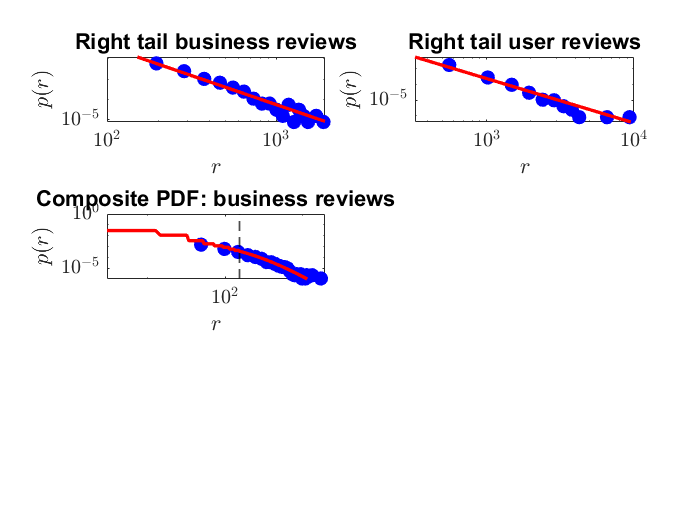

r1 =      7
     2
    35
    21
    19
    14
    24
    38
    50
    70



%%% Plots of PDF and complementary cumulative function

NB = 40; % Number of bins
% 
subplot(3,2,3)

h = histogram(r,NB,'Normalization','pdf');
plot(h.BinEdges(1:NB),h.Values,'ob','MarkerSize',8,'MarkerFaceColor','b')
hold on
x = linspace(min(r),max(r),1000);
hold on
plot(x,pdf(pd,x),'r-',"LineWidth",2)
xline(xmin,'--k','LineWidth',1);
xlim([min(r) max(r)])
ylim([10^-6 10^0])
set(gca,"YScale","log")
set(gca,"XScale","log")
xlabel('$r$','Interpreter','LaTex')
ylabel('$p(r)$','Interpreter','LaTex')
set(gca,'TickLabelInterpreter','LaTex')
set(gca,'FontSize',12)
%xline(xmin,'--k','LineWidth',1);
title('Composite PDF: business reviews')
hold off

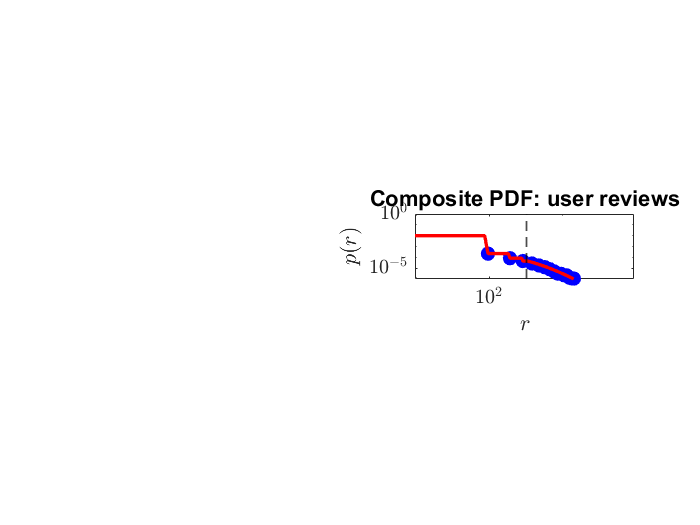

%%% Plots of PDF and complementary cumulative function
NB = 100; % Number of bins

subplot(3,2,4)
h1 = histogram(r1,NB,'Normalization','pdf');
plot(h1.BinEdges(1:NB),h1.Values,'ob','MarkerSize',8,'MarkerFaceColor','b')
hold on
x1 = linspace(min(r1),max(r1),1000);
hold on
plot(x1,pdf(pd1,x1),'r-',"LineWidth",2)
xline(xmin1,'--k','LineWidth',1);
xlim([min(r1) max(r1)])
ylim([10^-6 10^0])
set(gca,"YScale","log")
set(gca,"XScale","log")
xlabel('$r$','Interpreter','LaTex')
ylabel('$p(r)$','Interpreter','LaTex')
set(gca,'TickLabelInterpreter','LaTex')
set(gca,'FontSize',12)
%xline(xmin,'--k','LineWidth',1);
title('Composite PDF: user reviews')
hold off

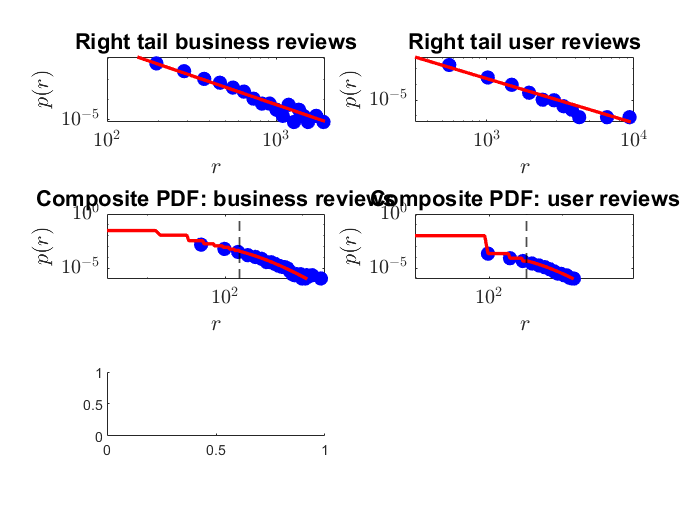

subplot(3,2,5)

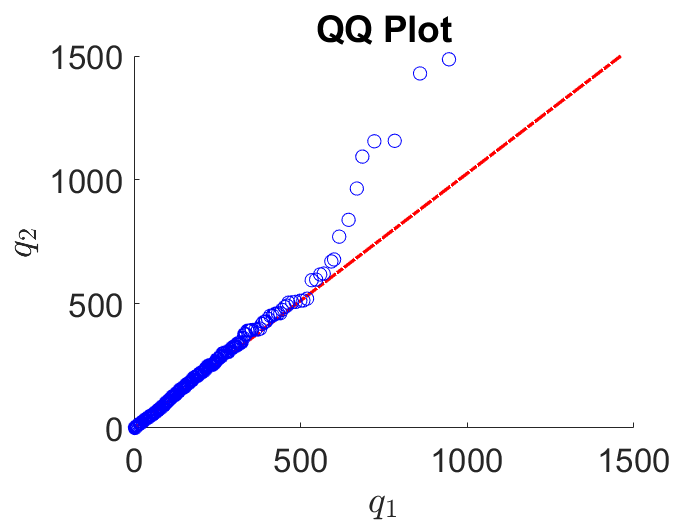

r=table2array(reviews_user);

figure(4)
b=Kernel.BandWidth;

pt=0.33; %fraction of data to use in trainign set
pv=0.33; %fraction of data to use in validation set
train_set=r(1:round(pt*length(r)));
N_T=length(train_set);
val_set=r(round(pt*length(r)+1:round((pt+pv)*length(r))));
test_set=r(round((pt+pv)*length(r))+1:end);

f = @(x,u) sum(1+erf((x-train_set)/sqrt(2*b^2)))/(2*N_T) - u;

n_rand = 5000; % Number of random numbers to be generated

kernel_random_numbers = []; % Vector to store all random numbers to be generated

for i = 1:n_rand
   
    u = rand; % Random number drawn from uniform distribution over [0,1] 
    
    y = fzero(@(x) f(x,u),0); % Numerical solution of the equation C(y)-u = 0
    
    kernel_random_numbers = [kernel_random_numbers; y];
    
end

%qqplot(x,y) displays a quantile-quantile plot of the quantiles of the sample data x versus the quantiles of the sample data y. If the samples come from the same distribution, then the plot appears linear.
%plot of the quantile of a target dist (line in red) vs. quantiles of an
%empirical dist. This allows us to conclude that we're doing a faily good
%job because the central body of the dist falls into the line.
%pvec = 0:1:100; % Vector of quantiles to be plotted
h = qqplot(r,kernel_random_numbers);%,pvec); %Double check
set(h(1),'marker','o','markersize',8,'markeredgecolor','blue');
set(h(2),'linewidth',2,'color','red');
set(h(3),'linewidth',2,'color','red');

set(gca,'FontSize',20)
title('QQ Plot')
xlabel('$q_1$','Interpreter','LaTex')
ylabel('$q_2$','Interpreter','LaTex')
ylim([0 1500])

pval=0.05;

[b,p] = kstest2(r,kernel_random_numbers,pval);
if b == 1
   fprintf('NH rejected at %3.2f significance level (p = %3.2e)\n',pval,p)
elseif b == 0
   fprintf('NH cannot be rejected at %3.2f significance level (p = %3.2e)\n',pval,p)
end

NH rejected at 0.05 significance level (p = 4.81e-29)



fprintf('\n')

n_rand1 = 5000; % Number of random numbers to be generated
u=rand(1,n)
compositepd_random_numbers1=xmin1*u.^(-1/alpha1);


%qqplot(x,y) displays a quantile-quantile plot of the quantiles of the sample data x versus the quantiles of the sample data y. If the samples come from the same distribution, then the plot appears linear.
%plot of the quantile of a target dist (line in red) vs. quantiles of an
%empirical dist. This allows us to conclude that we're doing a faily good
%job because the central body of the dist falls into the line.
%pvec = 0:1:100; % Vector of quantiles to be plotted

subplot(3,2,6)

h1 = qqplot(r1,compositepd_random_numbers1);%,pvec); %Double check
set(h1(1),'marker','o','markersize',8,'markeredgecolor','blue');
set(h1(2),'linewidth',2,'color','red');
set(h1(3),'linewidth',2,'color','red');

set(gca,'FontSize',12)
title('QQ Plot')
ylim([0 1500])
xlabel('$q_1$','Interpreter','LaTex')
ylabel('$q_2$','Interpreter','LaTex')
title('QQ-plot: user reviews')


pval=0.05;

[b1,p1] = kstest2(r1,compositepd_random_numbers1,pval);
if b1 == 1
   fprintf('NH rejected at %3.2f significance level (p = %3.2e)\n',pval,p1)
elseif b1 == 0
   fprintf('NH cannot be rejected at %3.2f significance level (p = %3.2e)\n',pval,p1)
end

fprintf('\n')

n_rand1 = 5000; % Number of random numbers to be generated
compositepd_random_numbers1=[]


compositepd_random_numbers1 =

     []



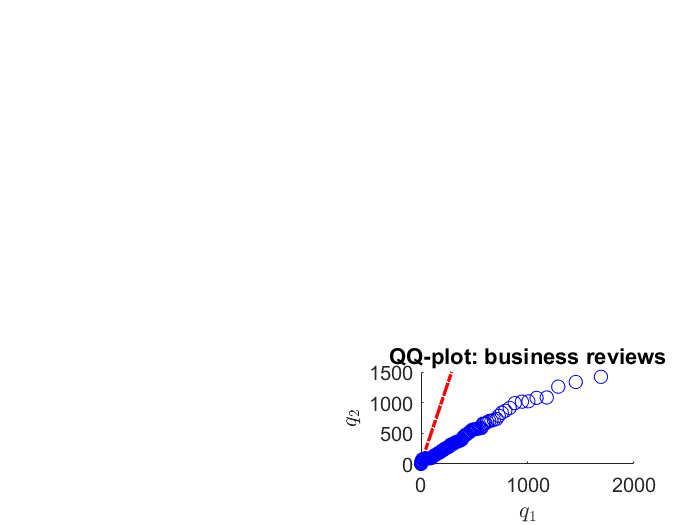


for i = 1:n_rand1
   
    u = rand; % Random number drawn from uniform distribution over [0,1] 
    
    y1=icdf(pd1,u);
    
    compositepd_random_numbers1 = [compositepd_random_numbers1; y1];
    
end

%qqplot(x,y) displays a quantile-quantile plot of the quantiles of the sample data x versus the quantiles of the sample data y. If the samples come from the same distribution, then the plot appears linear.
%plot of the quantile of a target dist (line in red) vs. quantiles of an
%empirical dist. This allows us to conclude that we're doing a faily good
%job because the central body of the dist falls into the line.
%pvec = 0:1:100; % Vector of quantiles to be plotted

subplot(3,2,6)

h1 = qqplot(r1,compositepd_random_numbers1);%,pvec); %Double check
set(h1(1),'marker','o','markersize',8,'markeredgecolor','blue');
set(h1(2),'linewidth',2,'color','red');
set(h1(3),'linewidth',2,'color','red');

set(gca,'FontSize',12)
title('QQ Plot')
ylim([0 1500])
xlabel('$q_1$','Interpreter','LaTex')
ylabel('$q_2$','Interpreter','LaTex')
title('QQ-plot: business reviews')



pval=0.05;

[b1,p1] = kstest2(r1,compositepd_random_numbers1,pval);
if b1 == 1
   fprintf('NH rejected at %3.2f significance level (p = %3.2e)\n',pval,p1)
elseif b1 == 0
   fprintf('NH cannot be rejected at %3.2f significance level (p = %3.2e)\n',pval,p1)
end

NH rejected at 0.05 significance level (p = 0.00e+00)



fprintf('\n')

n_rand1 = 5000; % Number of random numbers to be generated
u=rand(1,n)

u =     0.9991    0.1896    0.8796    0.7485    0.7651    0.9208    0.1226    0.4036    0.7764    0.4877    0.1932    0.2553    0.0886    0.3965    0.6474    0.6492    0.3633    0.0014    0.3538    0.4534    0.8158    0.8459    0.6192    0.2326    0.9666    0.3241    0.9129    0.9704    0.7920    0.7997    0.1538    0.5881    0.4216    0.1434    0.2940    0.9502    0.2054    0.4539    0.0900    0.0697    0.9809    0.1213    0.3864    0.7878    0.9801    0.9619    0.7079    0.9479    0.0849    0.4585


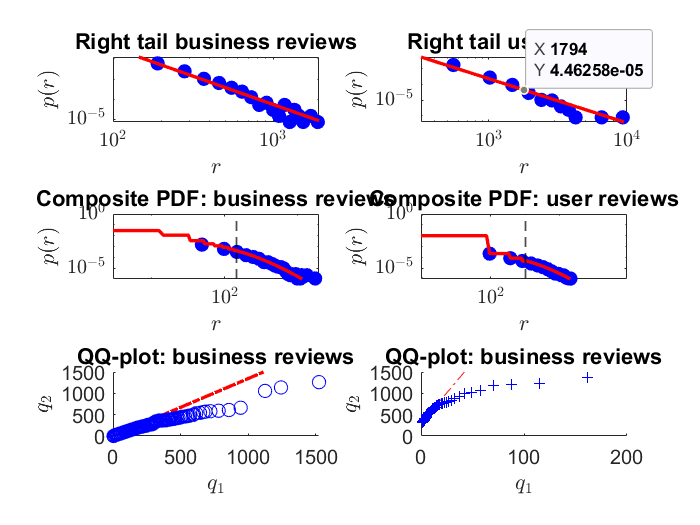

compositepd_random_numbers1=xmin1*u.^(-1/alpha1);


%qqplot(x,y) displays a quantile-quantile plot of the quantiles of the sample data x versus the quantiles of the sample data y. If the samples come from the same distribution, then the plot appears linear.
%plot of the quantile of a target dist (line in red) vs. quantiles of an
%empirical dist. This allows us to conclude that we're doing a faily good
%job because the central body of the dist falls into the line.
%pvec = 0:1:100; % Vector of quantiles to be plotted

subplot(3,2,6)

h1 = qqplot(r1,compositepd_random_numbers1);%,pvec); %Double check
set(h(1),'marker','o','markersize',8,'markeredgecolor','blue');
set(h(2),'linewidth',2,'color','red');
set(h(3),'linewidth',2,'color','red');

set(gca,'FontSize',12)
title('QQ Plot')
ylim([0 1500])
xlabel('$q_1$','Interpreter','LaTex')
ylabel('$q_2$','Interpreter','LaTex')
title('QQ-plot: business reviews')



pval=0.05;

[b1,p1] = kstest2(r1,compositepd_random_numbers1,pval);
if b1 == 1
   fprintf('NH rejected at %3.2f significance level (p = %3.2e)\n',pval,p1)
elseif b1 == 0
   fprintf('NH cannot be rejected at %3.2f significance level (p = %3.2e)\n',pval,p1)
end

NH rejected at 0.05 significance level (p = 1.32e-87)



fprintf('\n')


%Load the csv file for RQ2 that was preprocessed in Python
data_NV=readtable("yelp_Q2_NV.csv")

data_NV = 1396×15 table
           business_id                                   full_address                                                                                                                                                                                                    hours                                                                                                                                                                              open                                                        categories                                                            city            review_count                        name                           neighborhoods      longitude    state     stars    latitude                                       

data_AZ=readtable("yelp_Q2_AZ.csv")

data_AZ = 1599×15 table
           business_id                                full_address                                                                                                                                                                                                hours                                                                                                                                                                              open                                                       categories                                                        city        review_count               name               neighborhoods    longitude    state     stars    latitude                                                                              

%%%Compute and print the values of the first four moments%%%%
stars_NV=data_NV(:,"stars");
stars_NV=table2array(stars_NV);

stars_AZ=data_AZ(:,"stars");
stars_AZ=table2array(stars_AZ);

%Compute moments (BEFORE AGGREGATION) of the distribution of empirical data (using the explicit
%mathematical definitions of the moments).

%Estimate mean and standard deviation
N_NV=numel(stars_NV); %length of reviews vector 
m_NV = sum(stars_NV)/N_NV; % Compute mean and store value in variable
s_NV = sqrt(sum((stars_NV-m_NV).^2)/N_NV); % Compute std. deviation and store value in variable
fprintf('\n')
fprintf('Mean = %4.3f\n',m_NV)

Mean = 3.594


fprintf('Std. deviation = %4.3f\n',s_NV)

Std. deviation = 0.676



fprintf('Skewness = %4.3f\n',sum((stars_NV-m_NV).^3)/(N_NV*s_NV^3))

Skewness = -0.336



fprintf('Excess kurtosis = %4.3f\n',sum((stars_NV-m_NV).^4)/(N_NV*s_NV^4)-3)

Excess kurtosis = 0.405



fprintf('\n')
min(stars_NV)

ans = 1

max(stars_NV)

ans = 5

%Skewness and Excess kurtosis tells us whetehr our data is close to
%Gaussian (skewness=0 & kurtosis =3). A marekdly positive value indicates
%large excess kurotiss with respect to Gaussian. Empirical dist of returns
%is leptokurtic (significant kurtosis) --> our data have heavy tails. 
%Skewness measures symmetry. Gaussian is perfectly symmetric. our dist has
%positive skewness.

%Compute moments (BEFORE AGGREGATION) of the distribution of empirical data (using the explicit
%mathematical definitions of the moments).

%Estimate mean and standard deviation
N_AZ=numel(stars_AZ); %length of reviews vector 
m_AZ = sum(stars_AZ)/N_AZ; % Compute mean and store value in variable
s_AZ = sqrt(sum((stars_AZ-m_AZ).^2)/N_AZ); % Compute std. deviation and store value in variable
fprintf('\n')
fprintf('Mean = %4.3f\n',m_AZ)

Mean = 3.489


fprintf('Std. deviation = %4.3f\n',s_AZ)

Std. deviation = 0.691



fprintf('Skewness = %4.3f\n',sum((stars_AZ-m_AZ).^3)/(N_AZ*s_AZ^3))

Skewness = -0.268



fprintf('Excess kurtosis = %4.3f\n',sum((stars_AZ-m_AZ).^4)/(N_AZ*s_AZ^4)-3)

Excess kurtosis = 0.056



fprintf('\n')

%Skewness and Excess kurtosis tells us whetehr our data is close to
%Gaussian (skewness=0 & kurtosis =3). A marekdly positive value indicates
%large excess kurotiss with respect to Gaussian. Empirical dist of returns
%is leptokurtic (significant kurtosis) --> our data have heavy tails. 
%Skewness measures symmetry. Gaussian is perfectly symmetric. our dist has
%positive skewness.


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% Plot of empirical PDF vs Gaussian %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

n=500;
x = linspace(min(stars_NV),max(stars_NV),n); % Point grid between min and max return
g_NV = exp(-(x-m_NV).^2/(2*s_NV^2))/sqrt(2*pi*s_NV^2) % Gaussian PDF values computed on point grid

g_NV =     0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0014    0.0015    0.0016    0.0016    0.0017    0.0018    0.0018    0.0019    0.0020    0.0021    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029


%g=(exp(-m)*m.^x)./factorial(x)

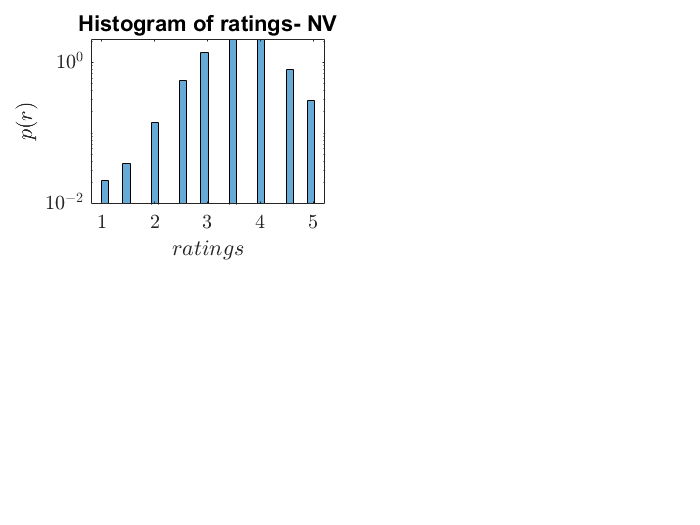

%Considering the skewness and Kurtosis we expect that the distribution is
%not Gaussian. In fact we expect large positive deviations from the mean
%and the presence of fat-tails. 
%Max likelihood tells that the most appropriate Gaussian dist to desribe
%the data is the one with same mean and std as the sample mean and std. 
%Will compare the empirical pdf of my data with the ML Gaussian pdf.

close all

subplot(2,2,1)

%plotting histogram of dataset to compare it with Gaussian

NB = 30; % Number of bins for histogram of returns
histogram(stars_NV,NB,'Normalization','PDF')
hold on
% plot(x,g_NV,'r','LineWidth',2)
set(gca,'YScale','log')  %log scale in y-axis to identify better the differences. Gaussian decaying exponentially- presence of fat tail is obvious
%log scale to identify better the deviations in the tail 
%set(gca,'XScale','log')  %log scale in y-axis to identify better the differences. Gaussian decaying exponentially- presence of fat tail is obvious

%ylim([10^-6 10^-2])
%xlim([min(r(r>0)) 1000])

%xlim([10^2 max(stars_NV)])
xlabel('$ratings$','Interpreter','LaTex')
ylabel('$p(r)$','Interpreter','LaTex')
set(gca,'TickLabelInterpreter','LaTex')
set(gca,'FontSize',12)
title('Histogram of ratings- NV')


%We observe large deviation from Gaussian in the right tail. Gaussian
%decays much faster(exponentially) while our distribution decays much
%slowly. (i.e. more extreme events than predicted by a Gaussian). THe exess
%of mass in the tail is compensated by a lack of mass in the centre.
%Visually validate clear differences between the empirical distribution and
%the Gaussian distribution

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%% Plot of empirical CCDF vs Gaussian %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%CCDF plot shows that the Gaussian distribution indicates higher probab of
% %%empirical pdfs for values greater than > r*
% %%probability
% x = sort(stars_NV); % Returns sorted in ascending order
% y = 1:1:length(stars_NV);
% y = 1 - y/(length(stars_NV)+1); % Calculating CCDF as rank-frequency plot
% %c = 0.5*(1 - erf((x-m_NV)./(s_NV*sqrt(2)))); % Gaussian CCDF
%  
% 
% subplot(2,2,2)
% semilogy(x,y,'b','LineWidth',2) %empirical CCDF of data
% hold on
% semilogy(x,c,'r','LineWidth',2)
% % set(gca,"Xscale","log")
% % ylim([1e-4 1])
% % xlim([min((r(r>0))) max(r)])
% xlabel('$reviews$','Interpreter','LaTex')
% ylabel('$C(r)$','Interpreter','LaTex')
% set(gca,'TickLabelInterpreter','LaTex')
% set(gca,'FontSize',12)
% title('CCDF ratings - NV')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% Plot of empirical PDF vs Gaussian %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

n=500;
x = linspace(min(stars_AZ),max(stars_AZ),n); % Point grid between min and max return
g_AZ = exp(-(x-m_AZ).^2/(2*s_AZ^2))/sqrt(2*pi*s_AZ^2) % Gaussian PDF values computed on point grid

g_AZ =     0.0009    0.0009    0.0010    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0014    0.0015    0.0016    0.0016    0.0017    0.0018    0.0018    0.0019    0.0020    0.0021    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0033    0.0034    0.0035    0.0036    0.0038    0.0039    0.0041    0.0042    0.0044    0.0045    0.0047    0.0049    0.0050    0.0052    0.0054    0.0056    0.0058


%g=(exp(-m)*m.^x)./factorial(x)

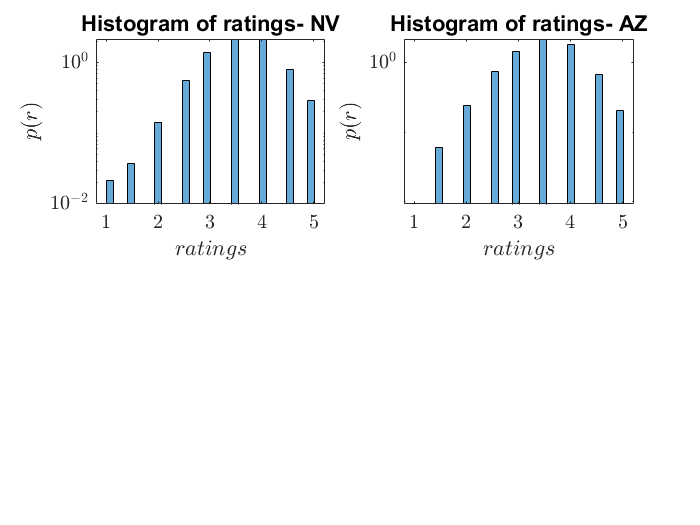

%Considering the skewness and Kurtosis we expect that the distribution is
%not Gaussian. In fact we expect large positive deviations from the mean
%and the presence of fat-tails. 
%Max likelihood tells that the most appropriate Gaussian dist to desribe
%the data is the one with same mean and std as the sample mean and std. 
%Will compare the empirical pdf of my data with the ML Gaussian pdf.

subplot(2,2,2)

%plotting histogram of dataset to compare it with Gaussian

NB = 30; % Number of bins for histogram of returns
histogram(stars_AZ,NB,'Normalization','PDF')
hold on
% plot(x,g_AZ,'r','LineWidth',2)
set(gca,'YScale','log')  %log scale in y-axis to identify better the differences. Gaussian decaying exponentially- presence of fat tail is obvious
%log scale to identify better the deviations in the tail 
%set(gca,'XScale','log')  %log scale in y-axis to identify better the differences. Gaussian decaying exponentially- presence of fat tail is obvious

%ylim([10^-6 10^-2])
%xlim([min(r(r>0)) 1000])

%xlim([10^2 max(stars_NV)])
xlabel('$ratings$','Interpreter','LaTex')
ylabel('$p(r)$','Interpreter','LaTex')
set(gca,'TickLabelInterpreter','LaTex')
set(gca,'FontSize',12)
title('Histogram of ratings- AZ')


%We observe large deviation from Gaussian in the right tail. Gaussian
%decays much faster(exponentially) while our distribution decays much
%slowly. (i.e. more extreme events than predicted by a Gaussian). THe exess
%of mass in the tail is compensated by a lack of mass in the centre.
%Visually validate clear differences between the empirical distribution and
%the Gaussian distribution

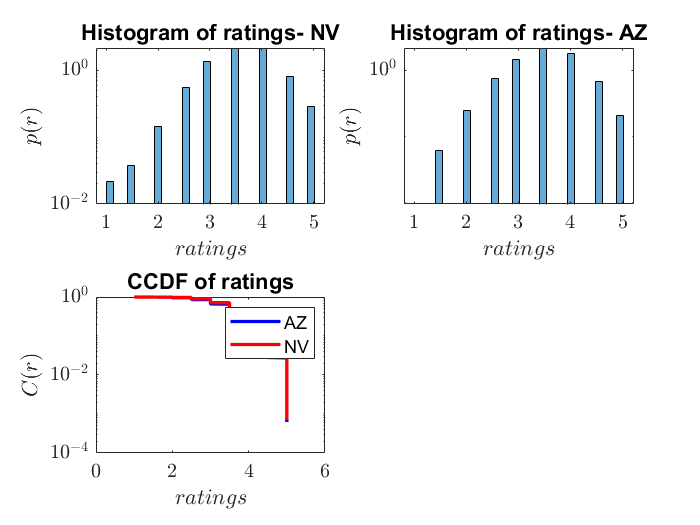

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% Plot of empirical CCDF vs Gaussian %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%CCDF plot shows that the Gaussian distribution indicates higher probab of
%%empirical pdfs for values greater than > r*
%%probability
x = sort(stars_AZ); % Returns sorted in ascending order
y = 1:1:length(stars_AZ);
y = 1 - y/(length(stars_AZ)+1); % Calculating CCDF as rank-frequency plot
%c = 0.5*(1 - erf((x-m_AZ)./(s_AZ*sqrt(2)))); % Gaussian CCDF
x1 = sort(stars_NV); % Returns sorted in ascending order
y1 = 1:1:length(stars_NV);
y1 = 1 - y1/(length(stars_NV)+1); % Calculating CCDF as rank-frequency plot
%c = 0.5*(1 - erf((x-m_AZ)./(s_AZ*sqrt(2)))); % Gaussian CCDF
 

subplot(2,2,3)
semilogy(x,y,'b','LineWidth',2) %empirical CCDF of data
hold on
semilogy(x1,y1,'r','LineWidth',2)
% set(gca,"Xscale","log")
% ylim([1e-4 1])
% xlim([min((r(r>0))) max(r)])
xlabel('$ratings$','Interpreter','LaTex')
ylabel('$C(r)$','Interpreter','LaTex')
set(gca,'TickLabelInterpreter','LaTex')
set(gca,'FontSize',12)
title('CCDF of ratings')
legend("AZ","NV")

%%%Test Similarities%%%

%h = kstest2(x1,x2) returns a test decision for the null hypothesis that the data in vectors x1 and x2 are from the same continuous distribution, using the two-sample Kolmogorov-Smirnov test. The alternative hypothesis is that x1 and x2 are from different continuous distributions. The result h is 1 if the test rejects the null hypothesis at the 5% significance level, and 0 otherwise.


pval=0.05;

[b,p] = kstest2(stars_NV,stars_AZ,pval);
if b == 1
   fprintf('NH rejected at %3.2f significance level (p = %3.2e)\n',pval,p)
elseif b == 0
   fprintf('NH cannot be rejected at %3.2f significance level (p = %3.2e)\n',pval,p)
end

NH rejected at 0.05 significance level (p = 7.31e-03)



fprintf('\n')

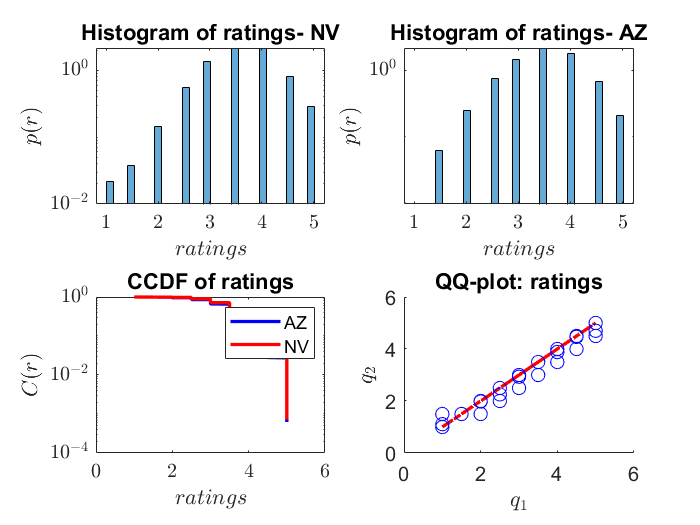

subplot(2,2,4)


h = qqplot(stars_NV,stars_AZ);%,pvec); %Double check
set(h(1),'marker','o','markersize',8,'markeredgecolor','blue');
set(h(2),'linewidth',2,'color','red');
set(h(3),'linewidth',2,'color','red');

set(gca,'FontSize',12)
title('QQ Plot')
%ylim([0 1500])
xlabel('$q_1$','Interpreter','LaTex')
ylabel('$q_2$','Interpreter','LaTex')
title('QQ-plot: ratings')

%Another option is the Cramer-von Mises test, which uses the squared L2 norm as the test statistic and is implemented in the dgof package as cvm.test(). The CVM test is 'better' in the sense that the distance metric takes into account the whole of the two ECDFs, rather than just picking out the largest distance
%https://uk.mathworks.com/matlabcentral/fileexchange/13407-two-sample-cramer-von-mises-hypothesis-test

pval=0.05;
[H, pValue, CM_limiting_stat] =cmtest2(stars_NV,stars_AZ,pval)

H = logical
   1


pValue = 1

CM_limiting_stat = 1.7046


if H == 0
   fprintf('Do not reject the null hypothesis at significance level ALPHA (p = %3.2e)\n',pval,pValue)
elseif H == 1
   fprintf('Reject the null hypothesis at significance level ALPHA (p = %3.2e)\n',pval,pValue)
end

Reject the null hypothesis at significance level ALPHA (p = 5.00e-02)
Reject the null hypothesis at significance level ALPHA (p = 1.00e+00)



fprintf('\n')
